# Praktikum 2 - Shift 1 Selasa 

`14 September 2021`

`Nama : ``Asisten Praktikum`

`NIM  :`

## Nomor 1

Amati grafik fungsi berikut !

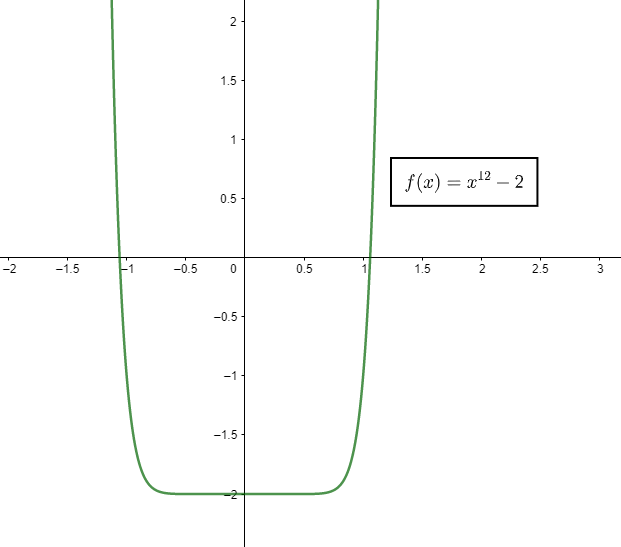

Diantara metode **bagi dua** dan metode **posisi palsu**, manakah yang lebih baik untuk mengaproksimasi akar dari fungsi tersebut? Sertakan alasan anda.

**Jawaban : **

Pada salah satu sisi akar, terdapat sisi yang landai sedangkan pada sisi lainnya sangatlah curam. Hal ini akan menyebabkan konvergensi dari metode posisi palsu terjadi dengan sangat lambat. 

Jadi pada kasus ini, **metode bagi dua** akan lebih baik untuk mengaproksimasi akar dari fungsi tersebut.

## Nomor 2

Apa yang dimodifikasi dari metode **posisi palsu** sehingga menghasillkan metode **modifikasi posisi palsu/*****modified false position*** ? Mengapa modifikasi ini dilakukan?

**Jawaban : **

Modifikasi dilakukan sebagai berikut : apabila salah satu ujung interval yang mengapir akar tidak mengalami perubahan selama dua atau lebih iterasi, maka pada iterasi berikutnya nilai fungsi di titik tersebut dikalikan setengahnya.

Hal ini untuk mencegah terjadinya *slow convergence* (konvergensi yang lambat) seperti yang dapat terjadi pada kasus di nomor 1, yaitu ketika kita berurusan dengan fungsi yang "landai"di salah satu sisinya, namun sangat curam di sisi lainnya.

## Nomor 3

Pada tahun 2250, umat manusia sudah mengembangkan pesawat super cepat yang memungkinkan umat manusia untuk menjelajahi planet di galaksi nan jauh. 

Di planet Kronos pada kuadran Beta, diketahui konsentrasi oksigen di udara ($O_{\textrm{level}}$) berubah - ubah tergantung dengan temperatur planet saat itu. Terdapat hubungan

### 
$$\ln \left(O_{\textrm{level}} \right)=1\ldotp 08+\frac{77\ldotp 6}{T}-\frac{501\ldotp 2}{T^2 }+\frac{1980\ldotp 1}{T^3 }$$


dengan $T$ adalah temperatur planet (°C) dan $O_{\textrm{level}}$ konsentrasi oksigen di udara (satuan dalam %). 

Diketahui bahwa persamaan tersebut akurat untuk temperatur $T$ di interval $\left\lbrack 20,60\right\rbrack$ derajat Celsius.

### **3A**

Dengan menggunakan alat pengukur konsentrasi oksigen pada siang hari, diperoleh bahwa konsentrasi oksigen di udara saat itu  $O_{\textrm{level}} =21%$. 

Bangun sebuah fungsi inline (gunakan anonymous function) $f\left(T\right)=1\ldotp 08+\frac{77\ldotp 6}{T}-\frac{501\ldotp 2}{T^2 }+\frac{1980\ldotp 1}{T^3 }-\ln \left(O_{\textrm{level}} \right)$ dengan $O_{\textrm{level}} =21%$ dan bangun plot $f\left(T\right)$ untuk $T\in \left\lbrack 20,60\right\rbrack$

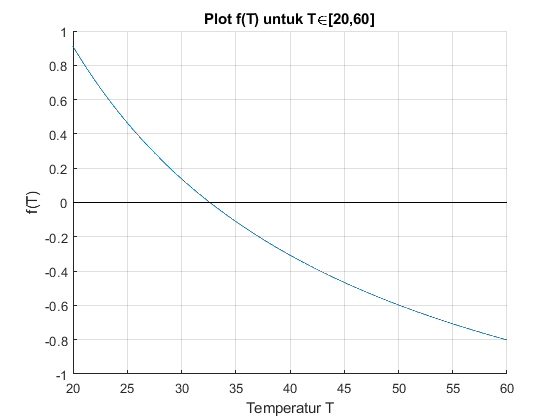

% Tulis jawaban anda dibawah garis
% --------------------------------
T = linspace(20, 60, 1000);
O_level = 21;
f = @(T) 1.08 + 77.6./T - 501.2./(T.^2) + 1980.1./(T.^3) - log(O_level);
Y = f(T);
figure
hold on
plot(T, Y)
plot(T, zeros(1,1000),'k')
ylabel('f(T)')
xlabel('Temperatur T')
title('Plot f(T) untuk T\in[20,60]')
grid on

### **3B**

Amati grafik pada bagian **3A**. Tentukanlah tebakan awal $a$ dan $b$ untuk menentukan akar dari $f\left(T\right)$dengan menggunakan **metode modifikasi posisi palsu,** dan jelaskan alasannya! (Asumsikan $a\le b$)

a = 30; % Tidak harus sama persis, yang penting mengapit akar
b = 35;

**Alasan :**

Karena dari grafik, dapat kita tinjau bahwa $f\left(30\right)>0$ sedangkan $f\left(35\right)<0$. Karena itu, interval $\left\lbrack 30,35\right\rbrack$ akan mengapit suatu akar dari $f\left(T\right)$.

### **3C**

Bangun fungsi pada file `ModFalsePos.m `yang menerima masukan berupa fungsi $f$, tebakan awal $a,b$ dan batas galat $\textrm{eps}$. 

Keluaran dari fungsi tersebut berupa hampiran nilai akar untuk fungsi $f$ menggunakan **metode modifikasi posisi palsu. **

(Gunakan $f$ yang sudah anda buat di bagian **3A)**

% Cek jawaban anda disini !
eps = 10^(-6);
T = ModFalsePos(f, a, b, eps);
fprintf("Jadi, nilai temperatur planet saat itu adalah %.4f derajat celsius.", T)

Jadi, nilai temperatur planet saat itu adalah 32.6283 derajat celsius.